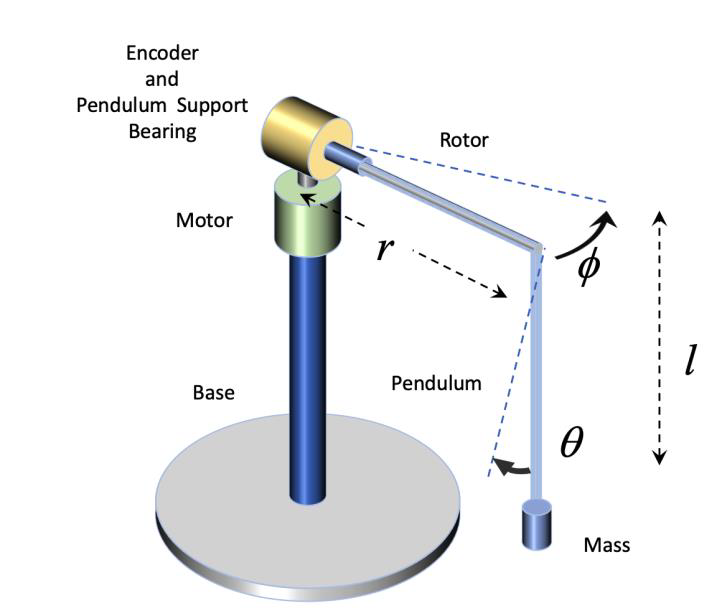

clear
clc

%Define symbolic variables
syms m g t b_1 b_2 Iz_1 real positive
syms r l tau_1 real
q_t = arrayfun(@(i) str2sym(['q_' num2str(i) '(t)']), 1:2);
q = arrayfun(@(i) str2sym(['q_' num2str(i)]), 1:2);
v = arrayfun(@(i) str2sym(['v_' num2str(i)]), 1:2);
v_t = arrayfun(@(i) str2sym(['v_' num2str(i) '(t)']), 1:2);
v_dot = arrayfun(@(i) str2sym(['v_dot_' num2str(i)]), 1:2);
assume(q_t, 'real');
assume(q, 'real');
assume(v, 'real');
assume(v_t, 'real');
assume(v_dot, 'real');

q_t=transpose(q_t);
q=transpose(q);
v=transpose(v);
v_dot=transpose(v_dot);
v_t =transpose(v_t);

q_t_dot=diff(q_t,t);
q_t_ddot=diff(q_t_dot,t);

v_t_dot = diff(v_t,t);

assume(q_t_dot, 'real');
assume(q_t_ddot, 'real');
assume(v_t_dot, 'real');

%forward kinematics
DH_table= [-pi/2, 0,0,q_t(1)-pi/2;...
            pi/2, 0, r, q_t(2)]

$$DH\_table = \left(\begin{array}{cccc} -\frac{\pi }{2} & 0 & 0 & q_{1}\left(t\right)-\frac{\pi }{2}\\ \frac{\pi }{2} & 0 & r & q_{2}\left(t\right) \end{array}\right)$$


[Tfull,Tparts,Tcumul ] = DH_full(DH_table);

o2Pm = [0;0;-l;1]

$$o2Pm = \left(\begin{array}{c} 0\\ 0\\ -l\\ 1 \end{array}\right)$$


o0Pm = Tfull*o2Pm

$$o0Pm = \left(\begin{array}{c} r\,\sin\left(\frac{\pi }{2}-q_{1}\left(t\right)\right)-l\,\sin\left(q_{2}\left(t\right)\right)\,\cos\left(\frac{\pi }{2}-q_{1}\left(t\right)\right)\\ r\,\cos\left(\frac{\pi }{2}-q_{1}\left(t\right)\right)+l\,\sin\left(q_{2}\left(t\right)\right)\,\sin\left(\frac{\pi }{2}-q_{1}\left(t\right)\right)\\ -l\,\cos\left(q_{2}\left(t\right)\right)\\ 1 \end{array}\right)$$

jac_m=jacobian(o0Pm(1:3),q_t)

$$jac\_m = \left(\begin{array}{cc} -r\,\cos\left(\frac{\pi }{2}-q_{1}\left(t\right)\right)-l\,\sin\left(q_{2}\left(t\right)\right)\,\sin\left(\frac{\pi }{2}-q_{1}\left(t\right)\right) & -l\,\cos\left(q_{2}\left(t\right)\right)\,\cos\left(\frac{\pi }{2}-q_{1}\left(t\right)\right)\\ r\,\sin\left(\frac{\pi }{2}-q_{1}\left(t\right)\right)-l\,\sin\left(q_{2}\left(t\right)\right)\,\cos\left(\frac{\pi }{2}-q_{1}\left(t\right)\right) & l\,\cos\left(q_{2}\left(t\right)\right)\,\sin\left(\frac{\pi }{2}-q_{1}\left(t\right)\right)\\ 0 & l\,\sin\left(q_{2}\left(t\right)\right) \end{array}\right)$$

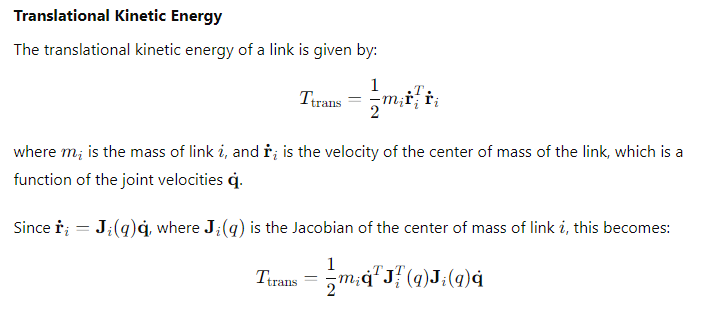

Ekin = simplify(0.5*m*transpose(q_t_dot)*(transpose(jac_m)*jac_m)*q_t_dot) ... % point mass kinetic energy
    + 0.5*q_t_dot(1)^2*Iz_1    % rotational kinetic energy of first axis

$$Ekin = \frac{{\mathrm{Iz}}_{1}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{l^{2}\,m\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{l^{2}\,m\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}}{2}+\frac{m\,r^{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}-\frac{l^{2}\,m\,{\cos\left(q_{2}\left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+l\,m\,r\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)$$

Since we modeled a point mass, there is nog contribution of rotational kinetic energy:

Otherwise (for 3 DOF):

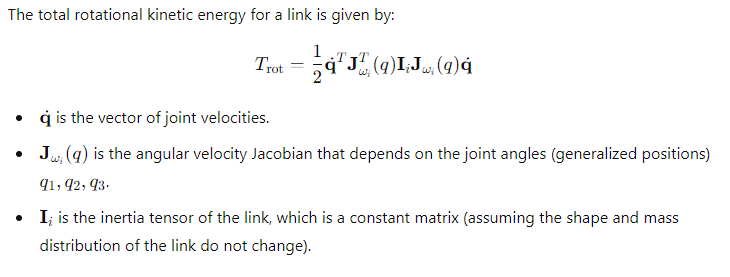

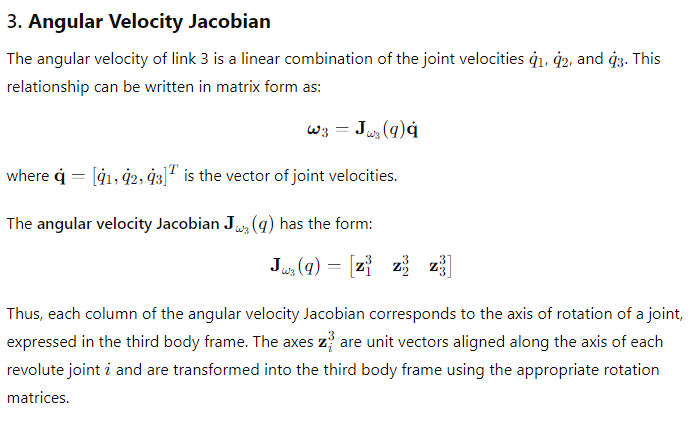

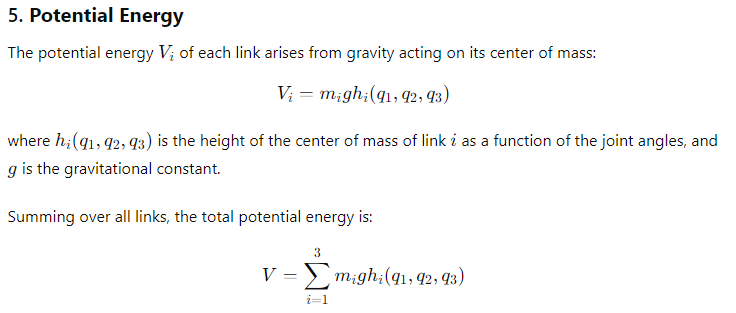

Epot = m*g*o0Pm(3,1)

$$Epot = -g\,l\,m\,\cos\left(q_{2}\left(t\right)\right)$$


L=Ekin-Epot %Lagrangian

$$L = \frac{{\mathrm{Iz}}_{1}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{l^{2}\,m\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{l^{2}\,m\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}}{2}+\frac{m\,r^{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}-\frac{l^{2}\,m\,{\cos\left(q_{2}\left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+g\,l\,m\,\cos\left(q_{2}\left(t\right)\right)+l\,m\,r\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)$$

Euler-lagrange with friction, but without holonomic constraints. Right hand side = Qi (generalized force i)

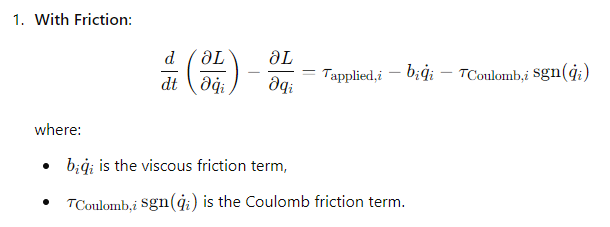

% generalized forces "Q", only viscous friction.
Q = [tau_1 - b_1*q_t_dot(1);-b_2*q_t_dot(2)]

$$Q = \left(\begin{array}{c} \tau_{1}-b_{1}\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ -b_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right) \end{array}\right)$$

tau=[tau_1;0]

$$tau = \left(\begin{array}{c} \tau_{1}\\ 0 \end{array}\right)$$


% derive equations of motion
[EOM, ~] = derive_EOM(L, q_t, Q)

$$EOM = \left(\begin{array}{c} -m\,l^{2}\,{\cos\left(q_{2}\left(t\right)\right)}^{2}\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)+m\,l^{2}\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)+m\,l\,r\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)+m\,r^{2}\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)+{\mathrm{Iz}}_{1}\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)-m\,\sin\left(q_{2}\left(t\right)\right)\,l\,r\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}+m\,\sin\left(2\,q_{2}\left(t\right)\right)\,l^{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+b_{1}\,\frac{\partial }{\partial t}q_{1}\left(t\right)-\tau_{1}\\ m\,l^{2}\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)+m\,r\,\cos\left(q_{2}\left(t\right)\right)\,l\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)-m\,\cos\left(q_{2}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\,l^{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}+b_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)+g\,m\,\sin\left(q_{2}\left(t\right)\right)\,l \end{array}\right)$$

%Substitute q1_ddot and q2_ddot into the equations
subs_eqns = subs(EOM, q_t_ddot, v_dot);
subs_eqns2 = subs(subs_eqns, q_t_dot, v);
subs_eqns3 = subs(subs_eqns2, q_t, q);
solve_EOM = subs_eqns3 == 0

$$solve\_EOM = \left(\begin{array}{c} m\,v_{1}\,\sin\left(2\,q_{2}\right)\,l^{2}\,v_{2}-m\,{\dot{v}}_{1}\,l^{2}\,{\cos\left(q_{2}\right)}^{2}+m\,{\dot{v}}_{1}\,l^{2}-m\,\sin\left(q_{2}\right)\,l\,r\,{v_{2}}^{2}+m\,{\dot{v}}_{2}\,l\,r\,\cos\left(q_{2}\right)+m\,{\dot{v}}_{1}\,r^{2}-\tau_{1}+{\mathrm{Iz}}_{1}\,{\dot{v}}_{1}+b_{1}\,v_{1}=0\\ b_{2}\,v_{2}+l^{2}\,m\,{\dot{v}}_{2}+g\,l\,m\,\sin\left(q_{2}\right)-l^{2}\,m\,{v_{1}}^{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)+l\,m\,r\,{\dot{v}}_{1}\,\cos\left(q_{2}\right)=0 \end{array}\right)$$


% Solve for q1_ddot and q2_ddot (i.e., dv1/dt and dv2/dt)
solution = solve(solve_EOM, v_dot);


% eqn = v==q_t_dot
eqn_vdot1=simplify(solution.v_dot_1)

$$eqn\_vdot1 = \frac{l\,\tau_{1}-b_{1}\,l\,v_{1}+b_{2}\,r\,v_{2}\,\cos\left(q_{2}\right)+\frac{g\,l\,m\,r\,\sin\left(2\,q_{2}\right)}{2}+l^{2}\,m\,r\,{v_{2}}^{2}\,\sin\left(q_{2}\right)-l^{2}\,m\,r\,{v_{1}}^{2}\,\left(\sin\left(q_{2}\right)-{\sin\left(q_{2}\right)}^{3}\right)-l^{3}\,m\,v_{1}\,v_{2}\,\sin\left(2\,q_{2}\right)}{l\,\left(-m\,l^{2}\,{\cos\left(q_{2}\right)}^{2}+m\,l^{2}-m\,r^{2}\,{\cos\left(q_{2}\right)}^{2}+m\,r^{2}+{\mathrm{Iz}}_{1}\right)}$$

eqn_vdot2=simplify(solution.v_dot_2)

$$eqn\_vdot2 = -\frac{l^{4}\,m^{2}\,{v_{1}}^{2}\,{\cos\left(q_{2}\right)}^{3}\,\sin\left(q_{2}\right)-\frac{\sin\left(2\,q_{2}\right)\,l^{4}\,m^{2}\,{v_{1}}^{2}}{2}+2\,l^{3}\,m^{2}\,r\,v_{1}\,v_{2}\,{\sin\left(q_{2}\right)}^{3}-2\,l^{3}\,m^{2}\,r\,v_{1}\,v_{2}\,\sin\left(q_{2}\right)+g\,l^{3}\,m^{2}\,{\sin\left(q_{2}\right)}^{3}-\frac{\sin\left(2\,q_{2}\right)\,l^{2}\,m^{2}\,r^{2}\,{v_{1}}^{2}}{2}+\frac{\sin\left(2\,q_{2}\right)\,l^{2}\,m^{2}\,r^{2}\,{v_{2}}^{2}}{2}-\frac{{\mathrm{Iz}}_{1}\,\sin\left(2\,q_{2}\right)\,l^{2}\,m\,{v_{1}}^{2}}{2}-b_{2}\,l^{2}\,m\,v_{2}\,{\cos\left(q_{2}\right)}^{2}+b_{2}\,l^{2}\,m\,v_{2}+g\,l\,m^{2}\,r^{2}\,\sin\left(q_{2}\right)-b_{1}\,l\,m\,r\,v_{1}\,\cos\left(q_{2}\right)+\tau_{1}\,l\,m\,r\,\cos\left(q_{2}\right)+{\mathrm{Iz}}_{1}\,g\,l\,m\,\sin\left(q_{2}\right)+b_{2}\,m\,r^{2}\,v_{2}+{\mathrm{Iz}}_{1}\,b_{2}\,v_{2}}{l^{2}\,m\,\left(-m\,l^{2}\,{\cos\left(q_{2}\right)}^{2}+m\,l^{2}-m\,r^{2}\,{\cos\left(q_{2}\right)}^{2}+m\,r^{2}+{\mathrm{Iz}}_{1}\right)}$$